clear; close all; clc

filepath = 'C:\Users\Martin\OneDrive - epfl.ch\PhD\3. My PhD courses\ENG606 - DOE\full_fact_2.xlsx';
data = readmatrix(filepath,Range="M2:U37");
 
y = data(:,5); %5 = t_rise
 
modelspec=[0 0 0 0; 1 0 0 0;
0 1 0 0;
0 0 1 0;
0 0 0 1;
1 1 0 0;
1 0 1 0;
1 0 0 1;
0 1 1 0;
0 1 0 1;
0 0 1 1;
1 1 1 0;
1 1 0 1;
1 0 1 1;
0 1 1 1;
1 1 1 1];
 
X=x2fx(data(:,1:4),modelspec)

X =      1     0    -1    -1    -1     0     0     0     1     1     1     0     0     0    -1     0
     1     0    -1     1    -1     0     0     0    -1     1    -1     0     0     0     1     0
     1     0     0    -1    -1     0     0     0     0     0     1     0     0     0     0     0
     1     0     0     1    -1     0     0     0     0     0    -1     0     0     0     0     0
     1     0     1    -1    -1     0     0     0    -1    -1     1     0     0     0     1     0
     1     0     1     1    -1     0     0     0     1    -1    -1     0     0     0    -1     0
     1    -1    -1    -1    -1     1     1     1     1     1     1    -1    -1    -1    -1     1
     1    -1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1     1    -1
     1    -1     0    -1    -1     0     1     1     0     0     1     0     0    -1     0     0
     1    -1     0     1    -1     0    -1     1     0     0    -1     0     0     1     0     0


 
 
coefficients = X'*y/36;
 
 
const = coefficients(1);
effects = coefficients(2:16);
 
 
%labels={'a_1';'a_2';'a_3';'a_4';...
%'a_{12}';'a_{13}';'a_{14}';'a_{23}';'a_{24}';'a_{34}'};

labels={'a_1';'a_2';'a_3';'a_4';...
'a_{12}';'a_{13}';'a_{14}';'a_{23}';'a_{24}';'a_{34}';...
'a_{123}';'a_{124}';'a_{134}';'a_{234}';...
'a_{1234}'};
 

figEffects=figure(1)

figEffects =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


bar(effects/const,'r')
set(gca, 'XTickLabel',labels)
title('Half relative effects','FontWeight','bold','FontSize',16)
xlabel('Coefficients')
ylabel('a_i/a_o')
 
 
figNormplot=figure(2)

figNormplot =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


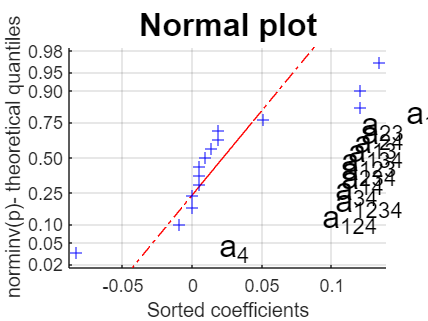

h=normplot(effects);
title('Normal plot','FontWeight','bold','FontSize',16)
xlabel('Sorted coefficients')
ylabel('norminv(p)- theoretical quantiles')
[E,index]=sort(effects);
text(h(1).XData+0.1, h(1).YData+.05, labels(index),'FontSize',16)

 

 
mdl = fitlm(data(:,1:4),y,'interactions')

mdl = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x1*x4 + x2*x3 + x2*x4 + x3*x4

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)        1.8519    0.046897        39.488    4.7654e-24
    x1                0.18056    0.057436        3.1436     0.0042655
    x2                0.20139    0.057436        3.5063     0.0017378
    x3                0.12037    0.046897        2.5667      0.016639
    x4              -0.083333    0.046897        -1.777      0.087746
    x1:x2             0.11458    0.070345        1.6289       0.11588
    x1:x3            0.020833    0.057436       0.36272       0.71986


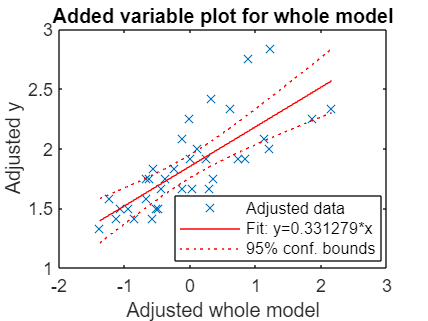

 

plot(mdl)

 
 
subject = ["Filling material","Filling density","On frame location", ...
      "Ambient temperature","Response"];
 
 
tableDOE = table(data(:,1),data(:,2),data(:,3),data(:,4),y,variableNames=subject);

% model spec --> "full" = all interactions, "interactions" = pairwise
% interactions, "linear" = main effects only

aov = anova(tableDOE,"Response", ModelSpecification="full")

aov = N-way anova, constrained (Type III) sums of squares.

Response ~ 1 + Filling material*Filling density + Filling material*On frame location + Filling material*Ambient temperature + Filling density*On frame location + Filling density*Ambient temperature + On frame location*Ambient temperature + Filling material:Filling density:On frame location + Filling material:Filling density:Ambient temperature + Filling material:On frame location:Ambient temperature + Filling density:On frame location:Ambient temperature + Filling material:Filling density:On frame location:Ambient temperature

                                                                              SumOfSquares    DF    MeanSquares     F     pValue
                                                                              ____________    __    ___________</




%m = multcompare(aov,["Ambient temperature","Filling density"])
%plotComparisons(aov,["Ambient temperature","Filling density"]);
 
%%
syms xa xd xm xl
D = inv(X'*X);
%fx = [1;xa;xd;xm;xl;xa*xd;xa*xm;xa*xl;xd*xm;xd*xl;xm*xl;xa*xd*xm;xa*xd*xl;xa*xm*xl;xd*xm*xl;xa*xd*xm*xl];
%v(xa,xd,xm,xl) = fx.'*D*fx;

fx = [1;xm;xd;xl;xa;xm*xd;xm*xl;xm*xa;xd*xl;xd*xa;xl*xa;xm*xd*xl;xm*xd*xa;xm*xl*xa;xd*xl*xa;xm*xd*xl*xa];
v(xa,xd,xm,xl) = fx.'*D*fx;

figVar=figure(3)

figVar =   Figure (EmbeddedFigure_Internal) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [360 178 560 420]
       Units: 'pixels'

  Show all properties


h1=fsurf(xm,xd,subs(v(xa,xd,xm,xl),[xa xl],[0 0]),[-1 1]);
 
 
h1.MeshDensity=15;

% xlabel('x_C',"FontSize",fz)
% ylabel('x_S',"FontSize",fz)
% zlabel('var(E)/sigma2',"FontSize",fz)


%%%%%%%%%%%%%%%%%%%%% storing data
foldername = 'FullFact_full_interactions';
mkdir(foldername)

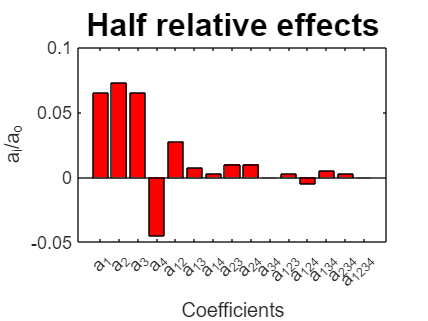

cd(foldername)

exportgraphics(figEffects,'halfeffects.eps');

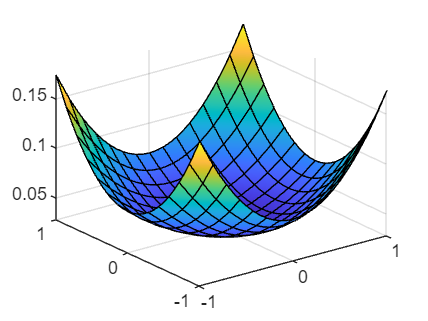

exportgraphics(figNormplot,'normplot.eps');

exportgraphics(figVar,'Variance_surf.eps');

%%% anova table
tblStr = formattedDisplayText(aov); 
out = regexprep( tblStr, '<\x2F?strong>', '' );
% Write string to file
fid = fopen('anovaTable.txt', 'wt');
fileCleanup = onCleanup(@()fclose(fid));
formatSpec = '%s\n';
fprintf(fid, formatSpec, out);
clear('fileCleanup')

%%% anova table
tblStr = formattedDisplayText(mdl); 
out = regexprep( tblStr, '<\x2F?strong>', '' );
% Write string to file
fid = fopen('mdlTable.txt', 'wt');
fileCleanup = onCleanup(@()fclose(fid));
formatSpec = '%s\n';
fprintf(fid, formatSpec, out);
clear('fileCleanup')

cd ..